# PlotPLC, the Plotting Tool for the Power Law Creep (PLC) Toolbox

This script plots Power Law Creep (PLC) Toolbox outputs as 2D images and provides a 1D plot of values across a horizontal, vertical, or diagonal cut plane / cross section. To use, define all variables listed in the **Setup** section, then *Run All*.

Author: Nick Richmond

Created: June 20, 2017

**Dependencies**:

***MATLAB Image Processing Toolbox***

PlotPLC uses the following normalized coordinate system:

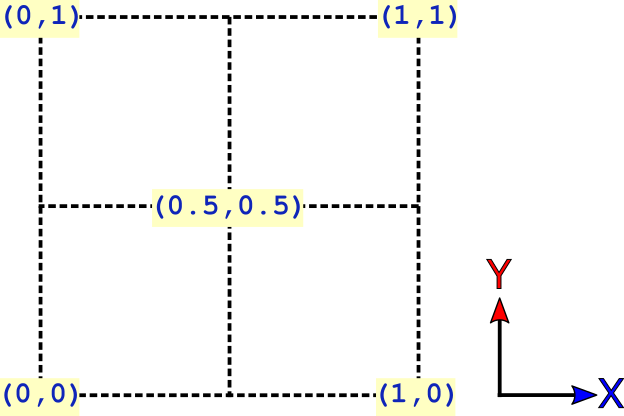

**NOTE**: The vertices labeled above are for demonstration only. When designating cut line vertices, use any vertex pair you please within the domain (0 <= x <= 1, 0 <= y <= 1).

## Setup

Choose your calculation and plotting preferences here. PlotPLC can automatically set a line of cross section across the area with the maxmimum gradient. 

if exist('AutoSavesDir','var') == 0
    AutoSavesDir = uigetdir(userpath,'Select PLC "Auto Saves" directory');
end
    

Would you like to save your plots as output files? If so, change save_figures to true.

save_figures = false; % set to true if you want to save the figure outputs

The project basename allows you to define how many PLC analyses to visualize. The more specific the project basename, the fewer the PLC runs will be visualized.

project_basename = 'Sawtooth_frequency'; % root name of the PLC runs of interest
parameter = 'stress'; % choose between 'stress' 'strain' 'visc' or 'pdd'
k_value = 10; % see k-value explainer below

K-Value explainer from PLC literature:

For **STRESSES**, k is as follows:

-   k=1 for deviatoric sigma_11 

-   k=2 for deviatoric sigma_22 

-   k=3 for deviatoric sigma_33 

-   k=4 for tau_32 

-   k=5 for tau_31 

-   k=6 for tau_12 

-   k=7 for max. principal dev. stress sigma1p 

-   k=8 for min. principal dev. stress sigma3p 

-   k=9 for max. shear stress 

-   k=10 for 2nd invariant of stress 

-   k=11 for trace of stress tensor (which can be used to obtain normal components)

For **STRAIN RATES**, k is as follows:

-   k=1 for epsdot_11 

-   k=2 for epsdot_22 

-   k=3 for epsdot_33 

-   k=4 for gammadot_32 

-   k=5 for gammadot_31 

-   k=6 for gammadot_12 

-   k=7 for max. principal strain rate epsdot_1p 

-   k=8 for min. principal strain rate epsdot_3p 

-   k=9 for 2nd strain rate invariant 

-   k=10 for trace of strain rate tensor (which can be used to obtain normal components) 

Would you like to calculate the gradient of your parameter of interest? If so, set calculate_gradient to true.

calculate_gradient = true;
    if calculate_gradient == true
        

If calculating the gradient, mask grains by phase number and set the gradient kernel here.

        phase_number_to_exclude = 2; % use [] if not excluding any phases
        gradient_kernel = 20;
    end

If you would like to have the line of cross section automatically generated by detecting the region with the highest gradient of your parameter of interest, set auto_xc_line to true. If you would prefer to define the vertices of the line of cross section, you may do so below.

auto_xc_line = true; % set to true to calculate the line of cross section automatically
    if calculate_gradient == false % overrides auto_xc_line if the gradient isn't being calculated
        auto_xc_line = false
    end       

How long should the line of cross section be? If unsure, try 0.2 to start, but keep in mind that this is the length over which the gradient will be searched.

    if auto_xc_line == true        
        auto_xc_linelength = 0.15; % length of the line of cross section
    end

If you want to explicitly define the vertices of the xc line, do so here:

    if auto_xc_line == false % set to true to dictate the location of the line of cross section    
        xc_vertices_begin = [0.5,0.25;... % [x1,y1;... vertex 1 of the first cut line (0 <= n <= 1)
                            0.5,0.75];    % x2,y2];    vertex 2 of the first cut line (0 <= n <= 1)
        theta = 0; % radians to rotate the cut line each run (default = 0, but try pi/6 if curious)
    end    

Use these controls to format your figures:

run_name_delimiter = '_'; % specify the character separating components of the
    % PLC run name (underscore is recommended)
run_name_legend_component = 3; % specify which component of the PLC run name
    % should be used in the line plot legend
varmag_component = 3; % specify which component of the PLC run name contains the
    % parameter of change
varmag_component_name = 'Frequency'; % specify the name of the parameter of change
x_axis_label = 'Length of Cut Line';
x_axis_unit = '(pixels)';
y_axis_label = '$2^{nd}$ Invariant $\sigma_{dev}$ tensor';
y_axis_unit = '(MPa)';
y_axis_gradient_unit = '(MPa/pixel)';
legend_title = 'Frequency (Hz)';
legend_loc_xcplot = 'southeast'; % legend location on figure; choose between 'northeast', 
    %'northwest', 'southeast', and 'southwest'
legend_loc_grad_xcplot = 'northeast'; % legend location on figure; choose between 'northeast', 
    %'northwest', 'southeast', and 'southwest'
legend_loc_maxmin = 'northwest'; % legend location on figure; choose between 'northeast', 
    %'northwest', 'southeast', and 'southwest'
temperature_interval = 1; % declare which PLC temperature interval is of interest
stress_strain_interval = 1; % declare which applied macro strain rate or stress 
    % interval is of interest

## Plot

NOTE: Nothing below this point requires changing unless you want to add new functionality.

All controls requiring changes from run to run are in the above 'SETUP' sections.

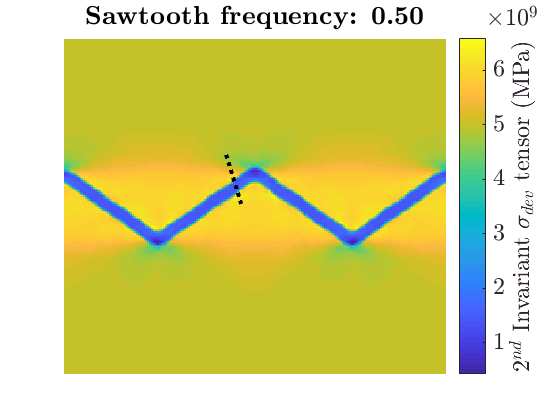

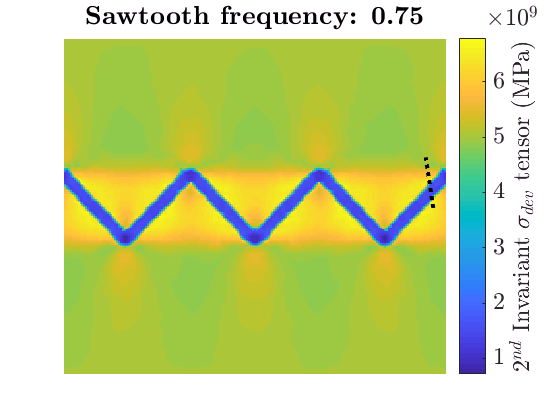

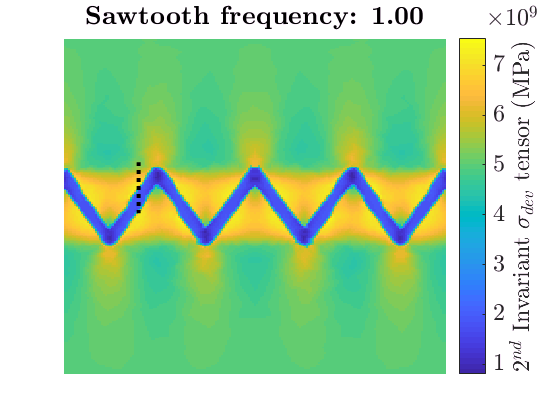

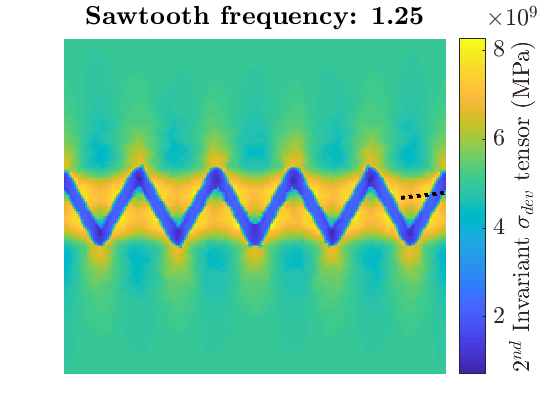

% PERFORM CALCULATIONS ON EACH PROJECT ITEM
cd(AutoSavesDir)
list_dir = dir(strcat(project_basename,'*'));
legend_items = cell(length(list_dir),1);
plc = PLCobject.empty(length(list_dir),0);
PLCvars = {parameter,temperature_interval,...
    stress_strain_interval,k_value,varmag_component};

for i = 1:length(list_dir)
    cd(list_dir(i).name);
    run = i;
    plc(i) = PLCobject(PLCvars,run_name_delimiter);
    
    if calculate_gradient == true
        if isempty(phase_number_to_exclude) == 0
            plc(i) = plc(i).CalculateGradient(auto_xc_linelength,phase_number_to_exclude);
        else
            plc(i) = plc(i).CalculateGradient(auto_xc_linelength);
        end
    end
    if auto_xc_line == true
        plc(i) = plc(i).CutLineMaxGradient();
    elseif auto_xc_line == false
        if theta ~= 0
            plc(i) = plc(i).RotateByTheta(i,theta,xc_vertices_begin);
        end
    end
    plc(i) = plc(i).SetCutLine;
    nx1 = plc(i).Normalize(plc(i).vx1,'x');
    ny1 = plc(i).Normalize(plc(i).vy1,'y');
    nx2 = plc(i).Normalize(plc(i).vx2,'x');
    ny2 = plc(i).Normalize(plc(i).vy2,'y');
    legend_items{i} = char(plc(i).fname_components(1,run_name_legend_component));
    legend_items{i} = strrep(legend_items{i}, ',', '.');
    plotlength = (plc(i).total_size(1)-1);
    cd ..\;
end

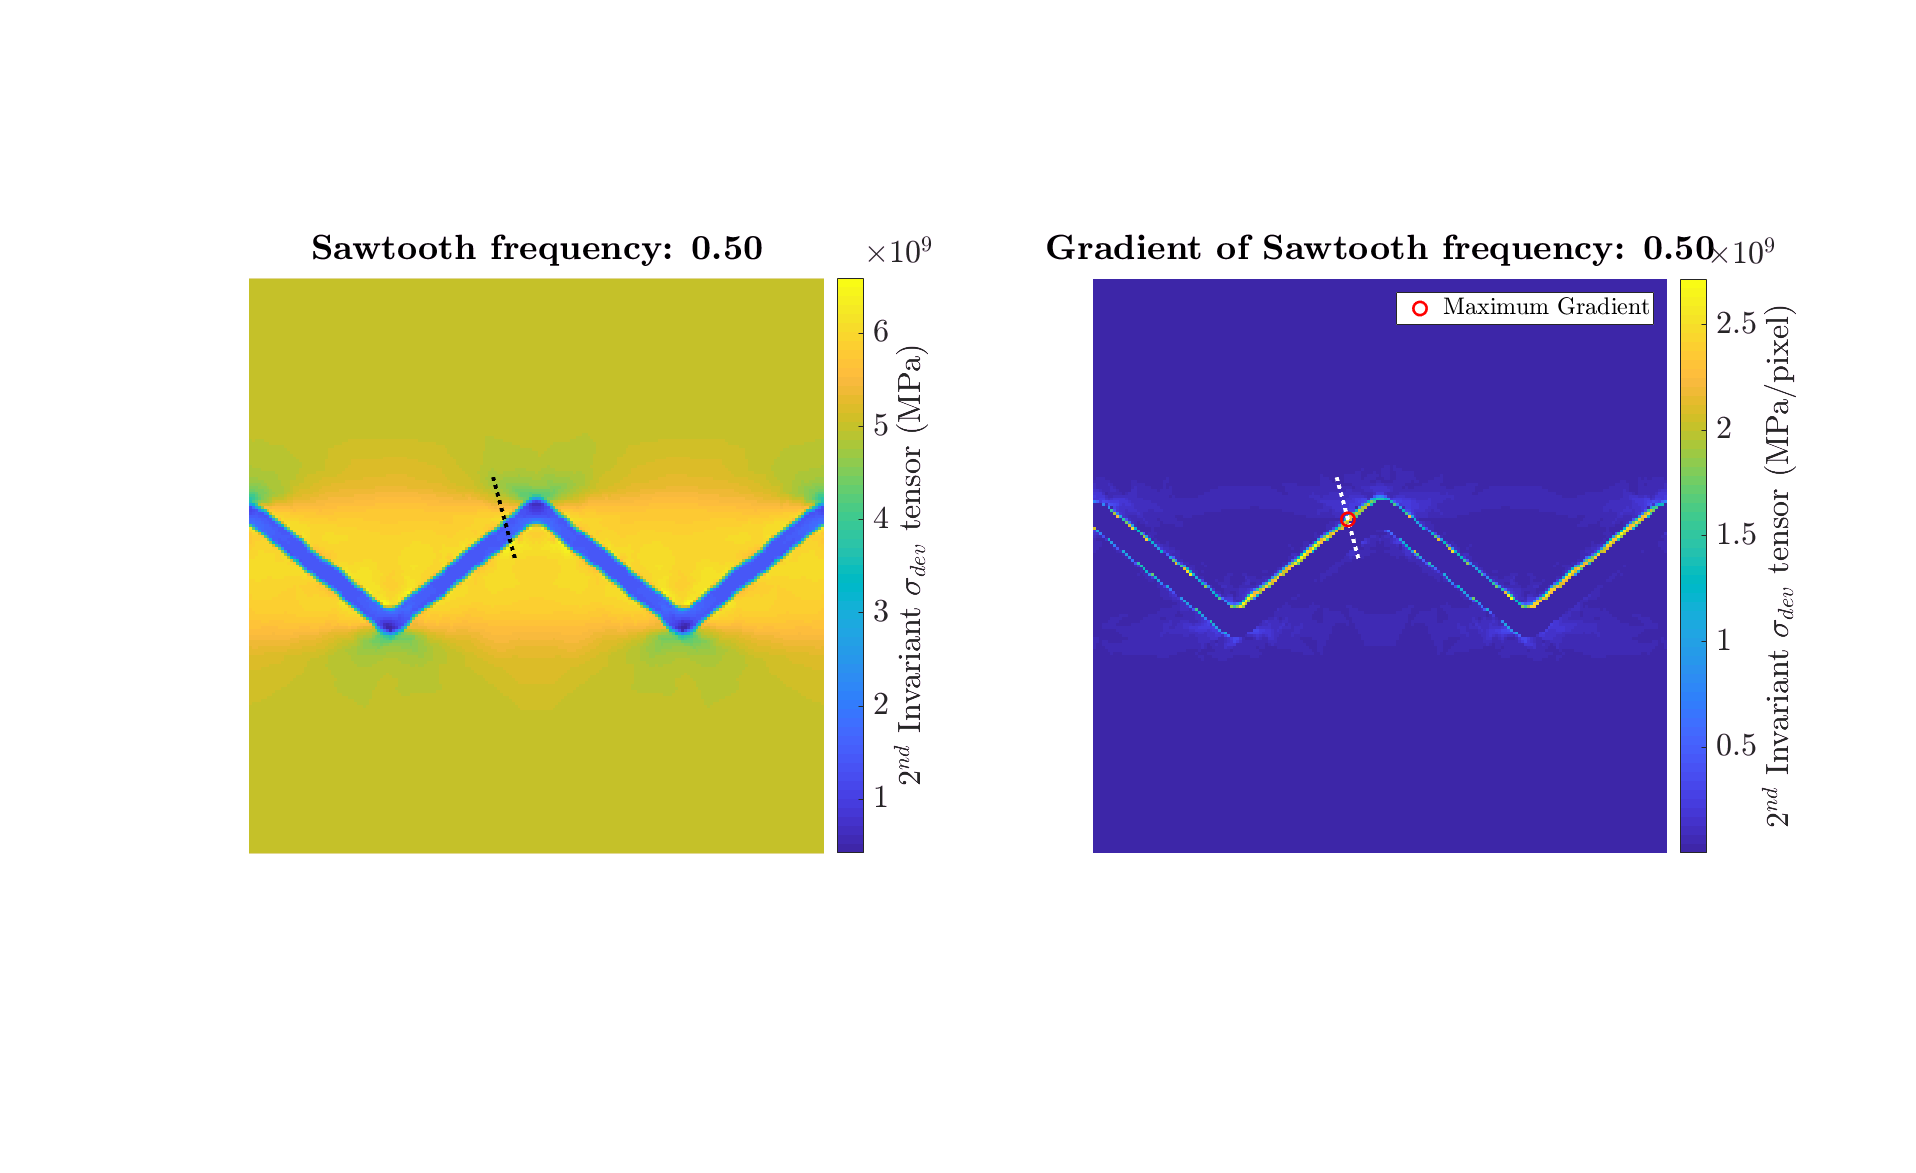

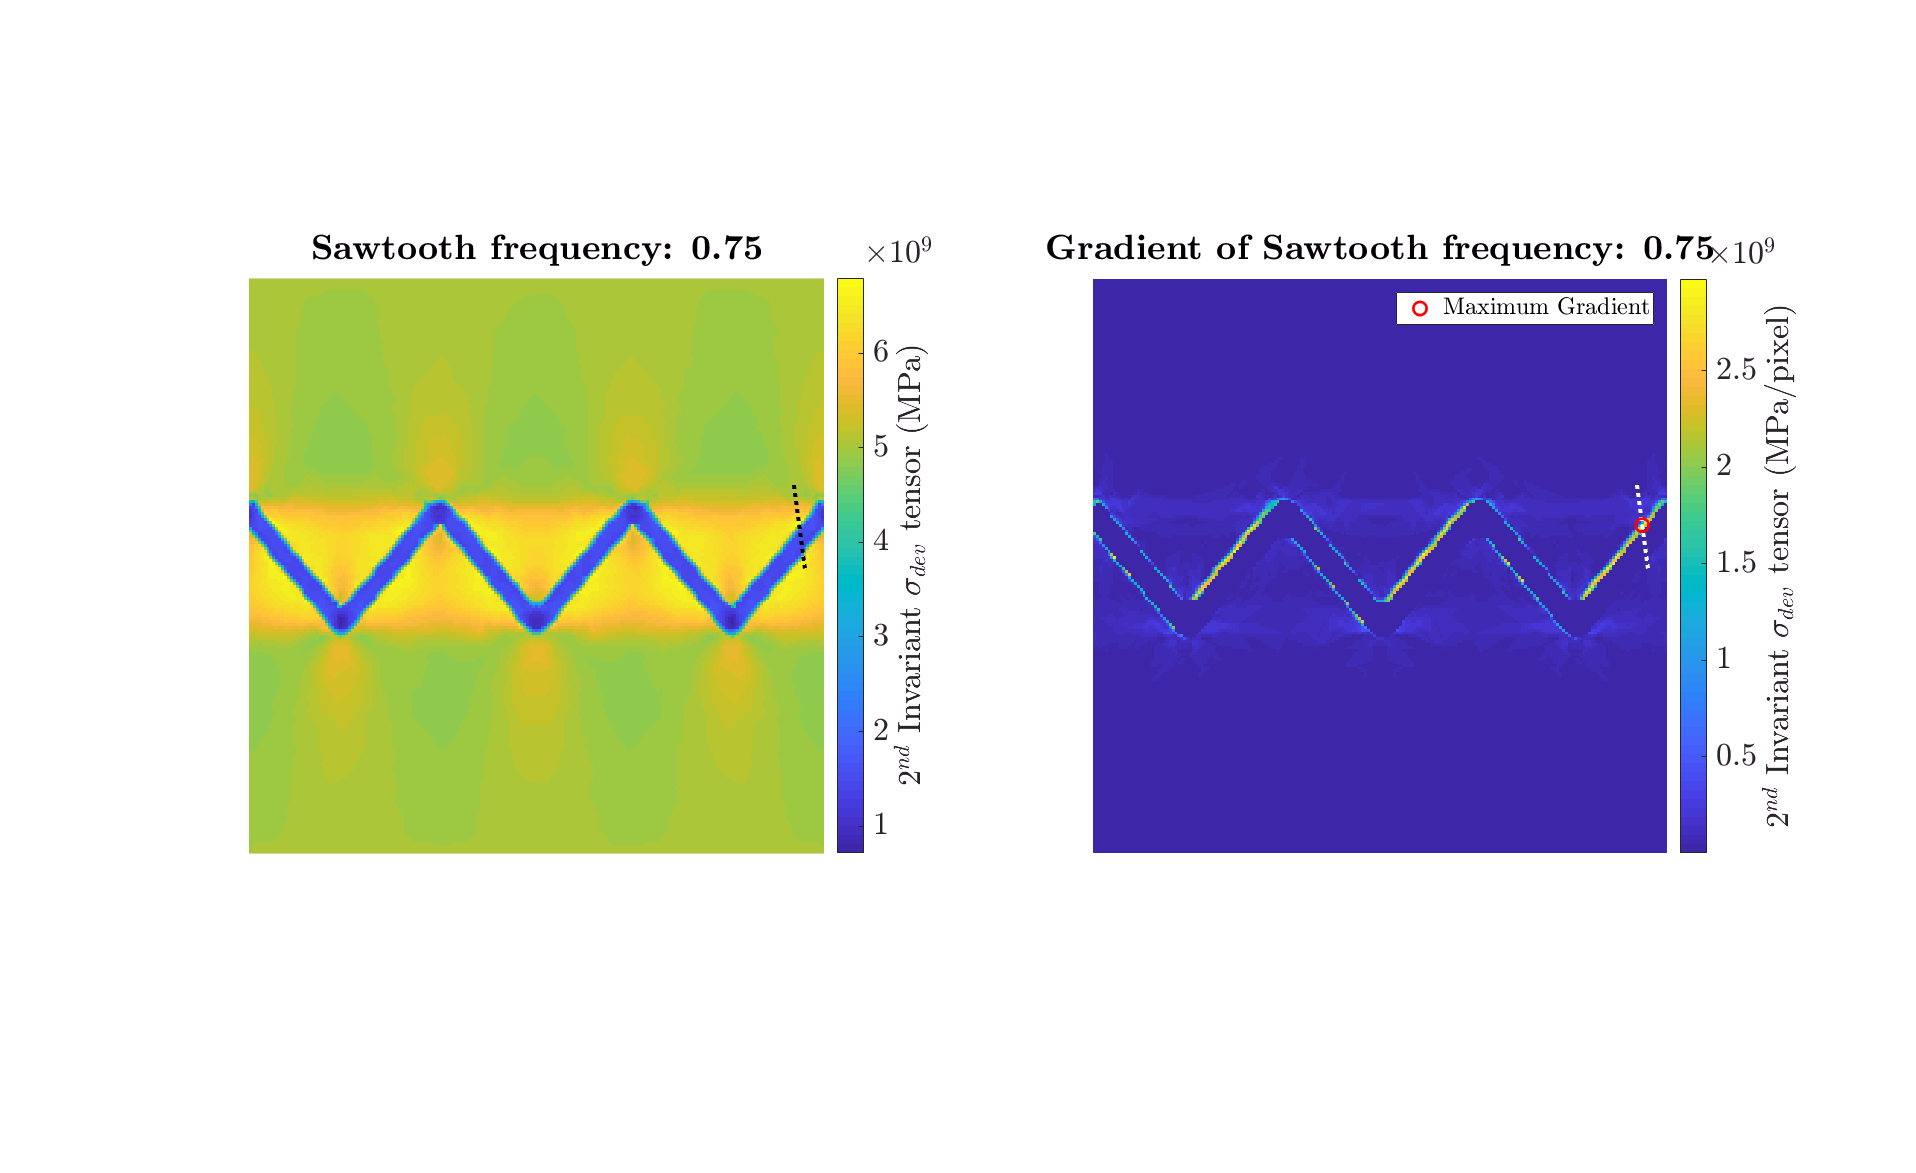

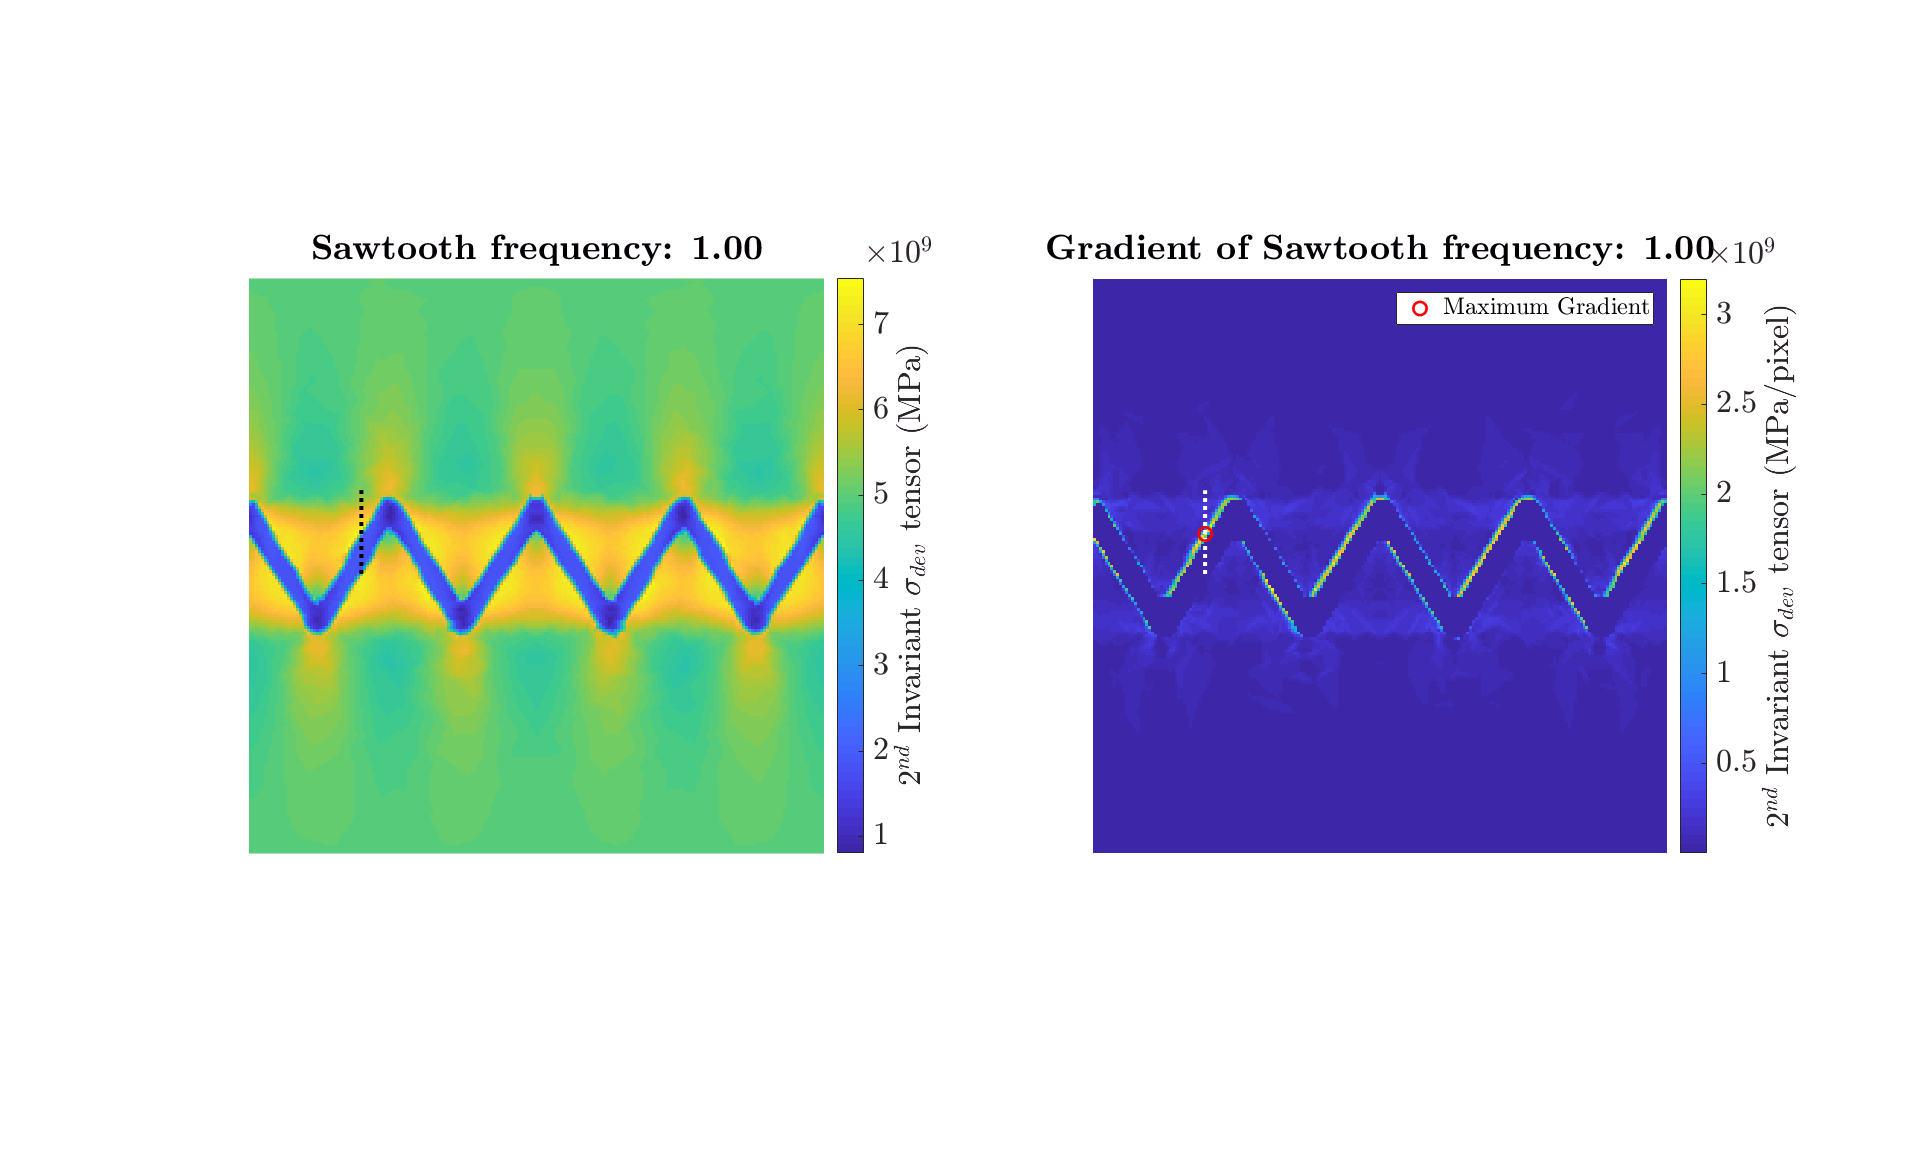

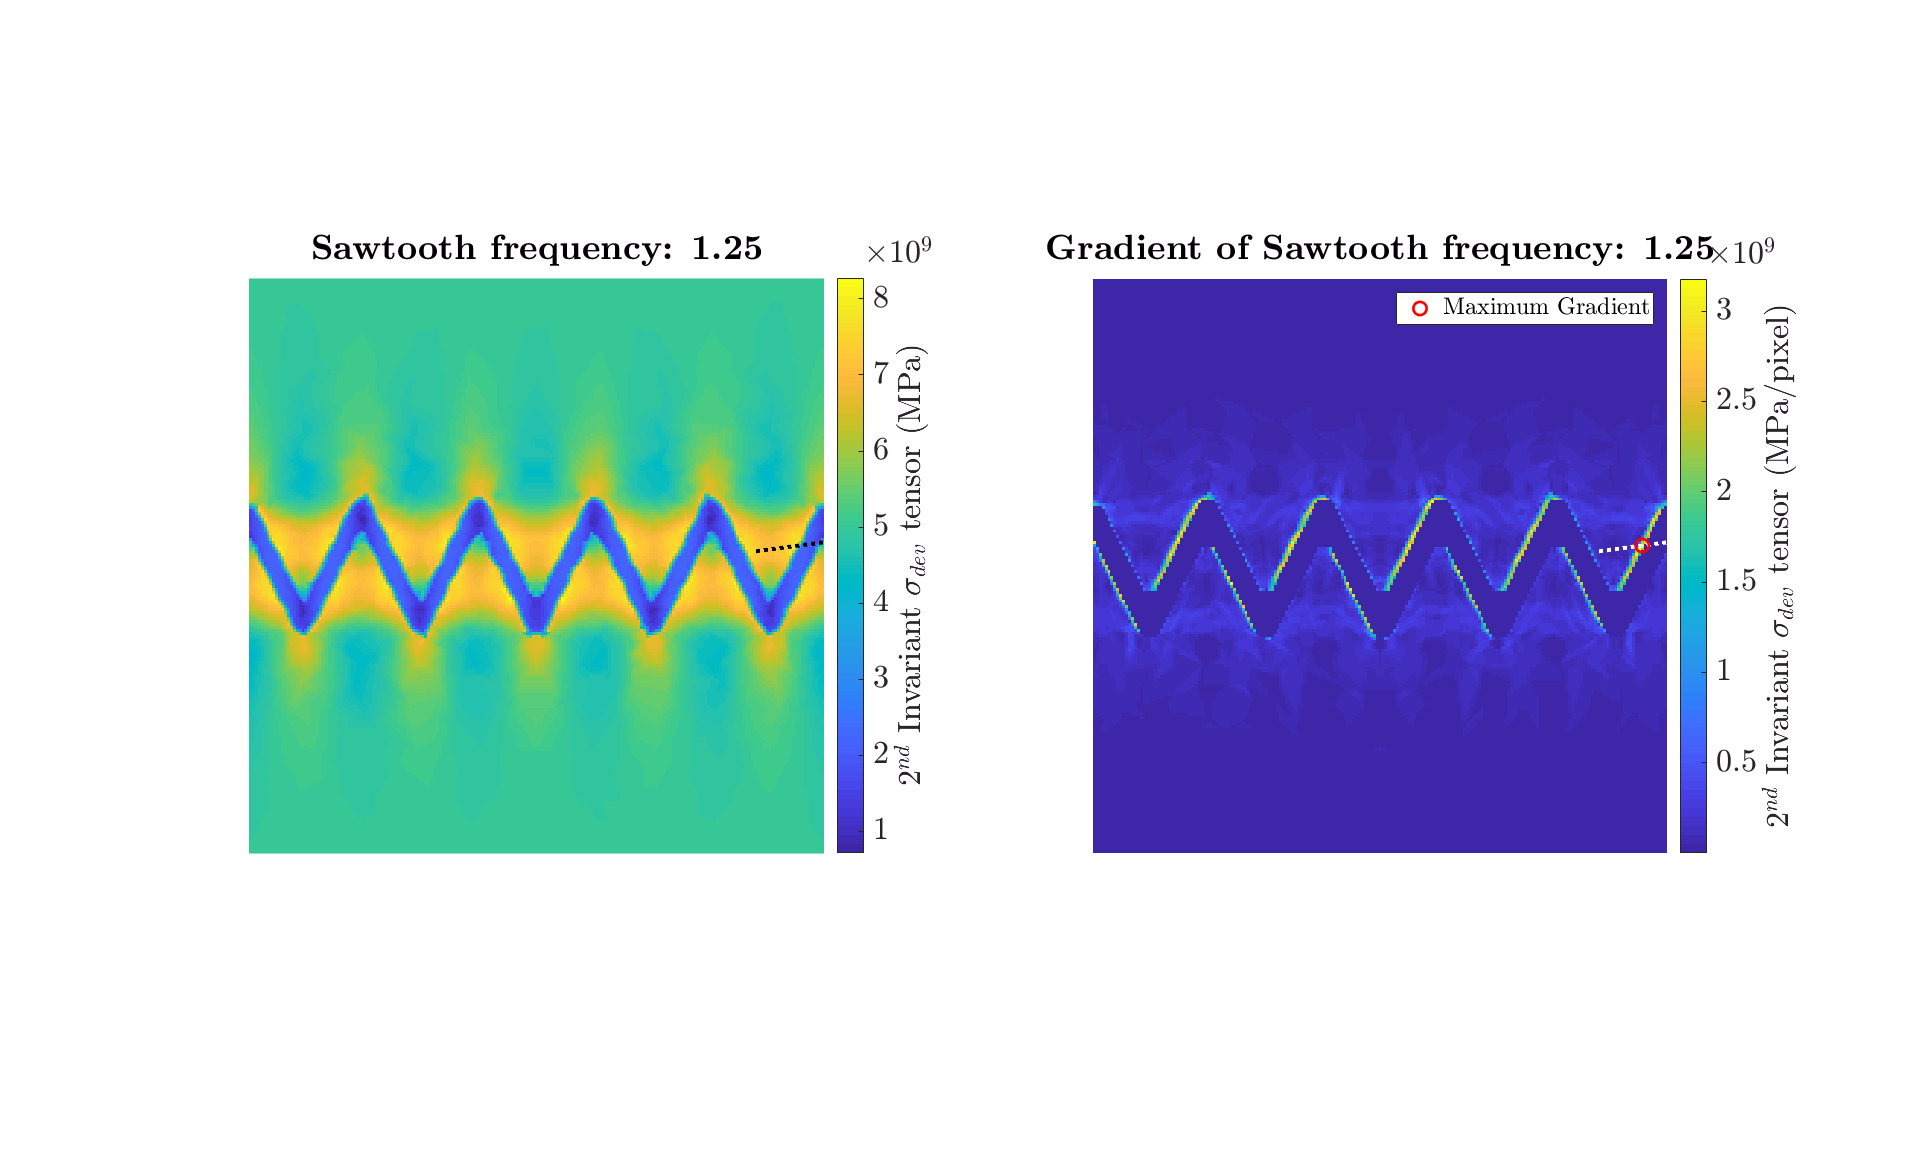

% PLOT THE PARAMETER OF INTEREST
for i = 1:length(plc)
parameterplot = figure('units','normalized'); % initialize plot of the entire domain
set(parameterplot,'Renderer','opengl','GraphicsSmoothing','on');
set(gca,'TickLabelInterpreter','latex','fontname','Century Schoolbook')

PLCplot(parameterplot,plc(i),plc(i).parameter_index);
title(['\textbf{',strrep(project_basename,'_',' '),': ',legend_items{i},'}'],...%char(plc(i).fname_components(run_name_legend_component))],...
        'Interpreter','latex','fontname','Century Schoolbook');
set(gca, 'visible', 'off') % remove the axes markers
set(findall(gca, 'type', 'text'), 'visible', 'on') % keep the plot title visible
c = colorbar;
c.Label.String = [y_axis_label,' ',y_axis_unit];
set(c,'TickLabelInterpreter','latex',...
    'fontname','Century Schoolbook','fontsize',18)
set(c.Label,'Interpreter','latex',...
    'fontname','Century Schoolbook','fontsize',18)
caxis auto
hold on
% add in the cross section line
plot([plc(i).vx1,plc(i).vx2],[plc(i).vy1,plc(i).vy2],'Color','black',...
    'LineStyle',':','LineWidth',3);
set(gca,'TickLabelInterpreter','latex',...
    'fontname','Century Schoolbook','fontsize',18)
end

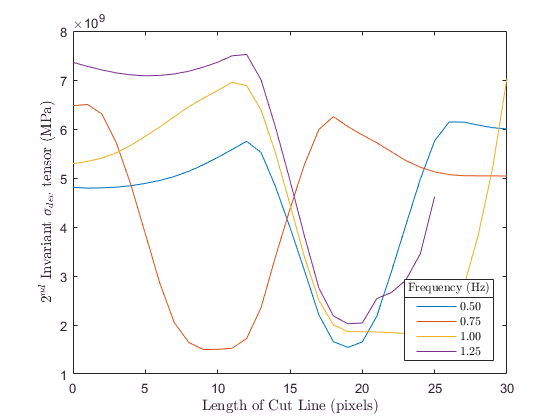

% CREATE A SUBPLOT FIGURE TO COMPARE THE PARAMETER OF INTEREST AND ITS GRADIENT

for i = 1:length(plc)
imageplot = figure('units','normalized','Position',[0 0 1 1]); % initialize plot of the entire domain
set(imageplot,'Renderer','opengl','GraphicsSmoothing','on');
set(gca,'TickLabelInterpreter','latex','fontname','Century Schoolbook')

PLCsubplot_parameters = {plc(i).parameter_index,plc(i).parameter_gradient};

% PLOT THE PARAMETER OF INTEREST
parametersubplot = PLCsubplot(imageplot,1,2,1,plc(i),PLCsubplot_parameters);
    title(['\textbf{',strrep(project_basename,'_',' '),': ',legend_items{i},'}'],... %'-',char(plc(i).fname_components(run_name_legend_component))],...
        'Interpreter','latex','fontname','Century Schoolbook');
    set(gca, 'visible', 'off') % remove the axes markers
    set(findall(gca, 'type', 'text'), 'visible', 'on') % keep the plot title visible
    c = colorbar;
    c.Label.String = [y_axis_label,' ',y_axis_unit];
    set(c,'TickLabelInterpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24)
    set(c.Label,'Interpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24)
    caxis auto
    hold on

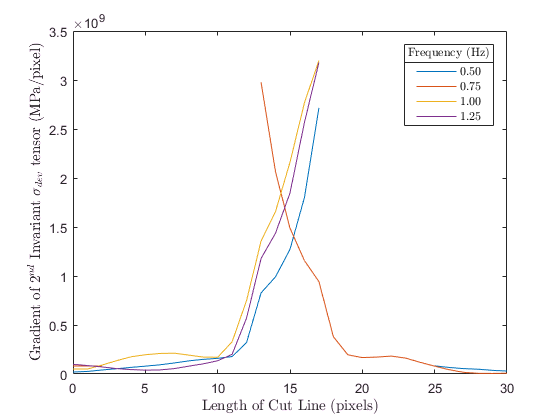

    % add in the cross section line
    plot([plc(i).vx1,plc(i).vx2],[plc(i).vy1,plc(i).vy2],'Color','black',...
        'LineStyle',':','LineWidth',3);
    set(gca,'TickLabelInterpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24)

% PLOT THE GRADIENT OF THE PARAMETER OF INTEREST
gradimagesubplot = PLCsubplot(imageplot,1,2,2,plc(i),PLCsubplot_parameters);
    title(['\textbf{','Gradient of ',strrep(project_basename,'_',' '),': ',legend_items{i},'}'],...%'-',char(plc(i).fname_components(run_name_legend_component)),],...
        'Interpreter','latex','fontname','Century Schoolbook');
    set(gca, 'visible', 'off') % remove the axes markers
    set(findall(gca, 'type', 'text'), 'visible', 'on') % keep the plot title visible
    c = colorbar;
    c.Label.String = [y_axis_label,' ',y_axis_gradient_unit];
    set(c,'TickLabelInterpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24);
    set(c.Label,'Interpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24);
    caxis auto
    hold on
    % add in the cross section line
    plot([plc(i).vx1,plc(i).vx2],[plc(i).vy1,plc(i).vy2],'Color','white',...
        'LineStyle',':','LineWidth',3)

    % add in a circle to highlight the area of maximum gradient
    maxcircle = plot(plc(i).max_gradient_col,plc(i).max_gradient_row,'o','MarkerSize',10,...
        'LineWidth',2,'Color','red');
    Lgrad = legend(maxcircle,'Maximum Gradient','Location','northeast');
    set(Lgrad,'Interpreter','latex',...
        'fontname','Century Schoolbook','fontsize',18);
    set(gca,'TickLabelInterpreter','latex',...
        'fontname','Century Schoolbook','fontsize',24)
    
% MAKE SUBPLOTS SQUARE
axesHandles = findobj(get(imageplot,'Children'), 'flat','Type','axes');
axis(axesHandles,'square');

end

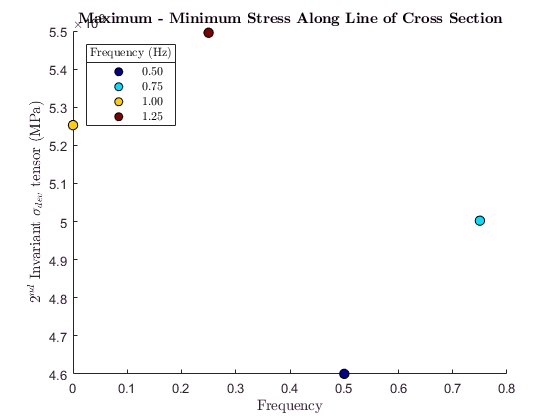

% PLOT THE PARAMETER OF INTEREST ALONG THE LINE OF CROSS SECTION
xcplot = figure; % initialize cut line / cross-section plot
set(xcplot,'Renderer','opengl','GraphicsSmoothing','on');
set(gca,'TickLabelInterpreter','latex','fontname','Century Schoolbook')
for i = 1:length(plc)
plot(0:(plc(i).vertex_distance)/(plc(i).vertex_distance):...
    ((plc(i).vertex_distance)),plc(i).cutline);
    % divide vertex distance by plotlength for normalized x-axis
hold on
end
L1 = legend(legend_items,'Location',legend_loc_xcplot);
L1_title = get(L1,'title');
set(L1,'Interpreter','latex',...
    'fontname','Century Schoolbook');
set(L1_title,'string',legend_title,'Interpreter','latex',...

    'fontname','Century Schoolbook');
xlbl = xlabel([x_axis_label,' ',x_axis_unit]);
ylbl = ylabel([y_axis_label,' ',y_axis_unit]);
set(xlbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')
set(ylbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')

% PLOT THE GRADIENT OF THE PARAMETER OF INTEREST ALONG THE LINE OF CROSS SECTION
gradplot = figure; % initialize gradient plot
set(gradplot,'Renderer','opengl','GraphicsSmoothing','on');
set(gca,'TickLabelInterpreter','latex','fontname','Century Schoolbook')
for i = 1:length(plc)
plot(0:(plc(i).grad_vertex_distance)/(plc(i).grad_vertex_distance)...
    :((plc(i).grad_vertex_distance)),plc(i).gradient_cutline);
    % divide vertex distance by plotlength for normalized x-axis
hold on
end
L2 = legend(legend_items,'Location',legend_loc_grad_xcplot);
L2_title = get(L2,'title');
set(L2,'Interpreter','latex',...
    'fontname','Century Schoolbook');
set(L2_title,'string',legend_title,'Interpreter','latex',...
    'fontname','Century Schoolbook');
xlbl = xlabel([x_axis_label,' ',x_axis_unit]);
ylbl = ylabel(['Gradient of ',y_axis_label,' ',y_axis_gradient_unit]);
set(xlbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')
set(ylbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')

% PLOT THE MAX-MIN OF THE PARAMETER OF INTEREST
minmaxplot = figure; % initialize plot of maximum-minimum value
set(minmaxplot,'Renderer','opengl','GraphicsSmoothing','on');
set(gca,'TickLabelInterpreter','latex','fontname','Century Schoolbook')
max_less_min = zeros(length(plc),2);
c = linspace(1,10,length(max_less_min));
marker_size = 50;
for i = 1:length(plc)
    max_less_min(i,:) = plc(i).MaxLessMin(varmag_component);
    scatter(max_less_min(i,1),max_less_min(i,2),marker_size,c(i),...
        'filled','MarkerEdgeColor','black')
    hold on
end
colormap(jet)
L3 = legend(legend_items,'Location',legend_loc_maxmin);
L3_title = get(L3,'title');
set(L3,'Interpreter','latex',...
    'fontname','Century Schoolbook');
set(L3_title,'string',legend_title,'Interpreter','latex',...
    'fontname','Century Schoolbook');
title(['\textbf{','Maximum - Minimum Stress Along Line of Cross Section','}'],...
        'Interpreter','latex','fontname','Century Schoolbook');
xlbl = xlabel(varmag_component_name);
ylbl = ylabel([y_axis_label,' ',y_axis_unit]);
set(xlbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')
set(ylbl,'Interpreter','latex',...
    'fontname','Century Schoolbook')

% SAVE THE FIGURES TO FILE
if save_figures == true
    h = get(0, 'children');
    if exist('Figures','dir') < 7
        mkdir Figures
    end
    cd('Figures');
    if exist(project_basename,'dir') < 7
        mkdir (project_basename);
    end
    cd(project_basename);
    for i=1:length(h)      
        saveas(h(i), [project_basename 'figure' num2str(h(i).Number)], 'epsc');
    end
    cd ..\..\;
end